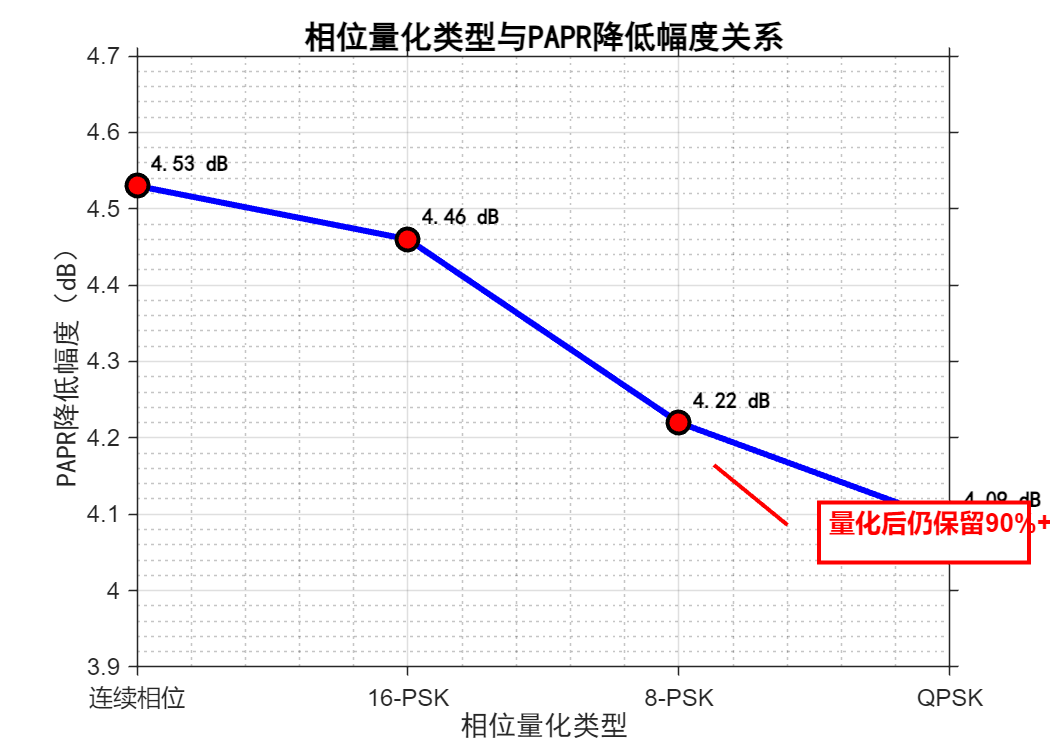

% 相位量化增益折线图（论文创新2核心效果，修正Arrow属性错误）
clear; clc; close all;

%% 1. 数据准备（严格对应论文数据）
quant_types = {'连续相位', '16-PSK', '8-PSK', 'QPSK'};  % 横轴：相位量化类型
papr_reduction = [4.53, 4.46, 4.22, 4.09];             % 纵轴：PAPR降低幅度（dB）
x = 1:length(quant_types);  % 横轴数值化（便于绘图）

%% 2. 计算增益保留比例（验证90%+）
max_gain = papr_reduction(1);  % 连续相位为最大增益（基准）
gain_ratio = papr_reduction / max_gain * 100;  % 各类型增益保留比例（%）
% 验证：最小比例（QPSK）≈4.09/4.53≈90.3%，符合“90%+”结论

%% 3. 绘图设置（适配PPT，突出核心信息）
figure('Position', [100, 100, 700, 500]);  % 画布大小（宽×高）
set(gcf, 'Color', 'white');  % 白色背景，适配PPT

% 绘制折线图（加粗线条+填充数据点，突出）
plot(x, papr_reduction, 'b-', 'LineWidth', 3); hold on;
scatter(x, papr_reduction, 120, 'red', 'filled', 'MarkerEdgeColor', 'black', 'LineWidth', 2);

% 标注每个数据点的具体数值（黑色粗体，清晰可读）
for i = 1:length(x)
    text(x(i)+0.05, papr_reduction(i)+0.03, sprintf('%.2f dB', papr_reduction(i)), ...
         'FontSize', 11, 'FontWeight', 'bold', 'Color', 'black');
end

% 标注核心结论（红色文本框+箭头，强化记忆）
% 修正：ArrowHeadSize → HeadSize；微调坐标，确保箭头指向QPSK数据点（x=4,y=4.09）
annotation('arrow', [0.75, 0.68], [0.3, 0.38], ...  % 归一化坐标，精准指向QPSK
           'Color', 'red', 'LineWidth', 2, 'HeadSize', 0.08);
annotation('textbox', [0.78, 0.25, 0.2, 0.08], ...
           'String', '量化后仍保留90%+增益', ...
           'FontSize', 13, 'FontWeight', 'bold', 'Color', 'red', ...
           'BackgroundColor', 'white', 'EdgeColor', 'red', 'LineWidth', 2);

%% 4. 图形美化与坐标设置
% 横轴标签（替换数值为量化类型，中文适配）
set(gca, 'XTick', x, 'XTickLabel', quant_types, 'FontSize', 12);
xlabel('相位量化类型', 'FontSize', 14);
ylabel('PAPR降低幅度（dB）', 'FontSize', 14);
title('相位量化类型与PAPR降低幅度关系', 'FontSize', 16, 'FontWeight', 'bold');

% 纵轴范围（聚焦数据区间，突出小幅变化）
ylim([3.9, 4.7]);  % 上下预留0.1~0.2dB空白，避免数据点贴边
grid on; grid minor;  % 网格辅助观察
set(gca, 'TickDir', 'out');  % 刻度向外，更美观
set(findall(gcf, 'Type', 'Text'), 'FontName', 'SimHei');  % 中文显示正常（避免乱码）


% 线条平滑优化
set(findall(gcf, 'Type', 'Line'), 'LineSmoothing', 'on');